clear
clc

**Selecting the file**

filename=''; %initializing the filename variable to an empty string

while contains(filename, '.abf') == 0 
    [filename, pathname] = uigetfile('C:\Desktop\*.abf', 'Select your .abf file');  %opening a user interface window to look for an abf file

    if contains(filename, '.abf') == 0
    w = warndlg('Attention, no .abf has been selected!', 'No file selected'); %throwing a warning dialog if no abf has been selected 
    waitfor(w);
    end
    close all
end

**Loading the selected signals from the .abf file**

[~,si, h] = abfload([pathname filename], 'info'); %load the info of the abf file: sampling interval and metadata
chNames = h.recChNames; %get a cell array containing the names of the recorded channels 

tf = 0; %initializing tf, it is just a way to check if a selection will be taken
while tf == 0
    [indx, tf] = listdlg('PromptString','Select 2 signals.','ListString', chNames); %select 2 signals from the .abf

    if size(indx) ~= 2
        w = warndlg ('Attention, you have selected a number of channels different than 2', 'Selection error') %throw an error if you selected a number of signals different than 2
        tf = 0;
        waitfor(w);
    end
    close all
end


si = si*1e-6; % sampling interval in seconds
file = abfload([pathname filename], 'channels', chNames(indx)); %loading the selected file and signals

opening C:\Users\anlo5007\Box\TH-Cre tomato testing\THcre-tdTomato_Ephys\20Sep2022\22920002.abf..
**** available channels:
    {'Im_prime' }
    {'Vm_sec'   }
    {'Im_prime2'}
    {'Vm_sec2'  }

data were acquired in gap-free mode
total length of recording: 861.6 s ~ 14 min
sampling interval: 100 µs
memory requirement for complete upload in matlab: 263 MB
reading file in 5260 chunks of ~0.05 Mb


time = (0:si:size(file,1)*si)'; %creating a time vector given the SI
time = time(1:end-1); %I´ve realized it was one element longer

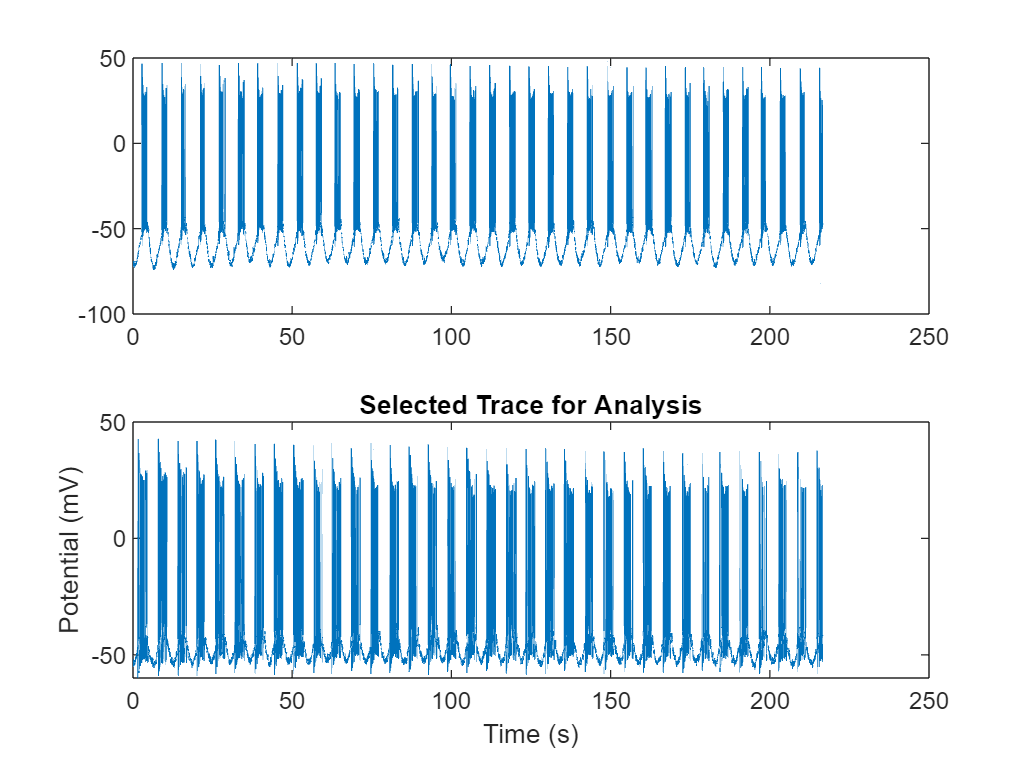

test = rangeselectionV2([time, file(:,1), file(:,2)]); %selecting the range to analyze

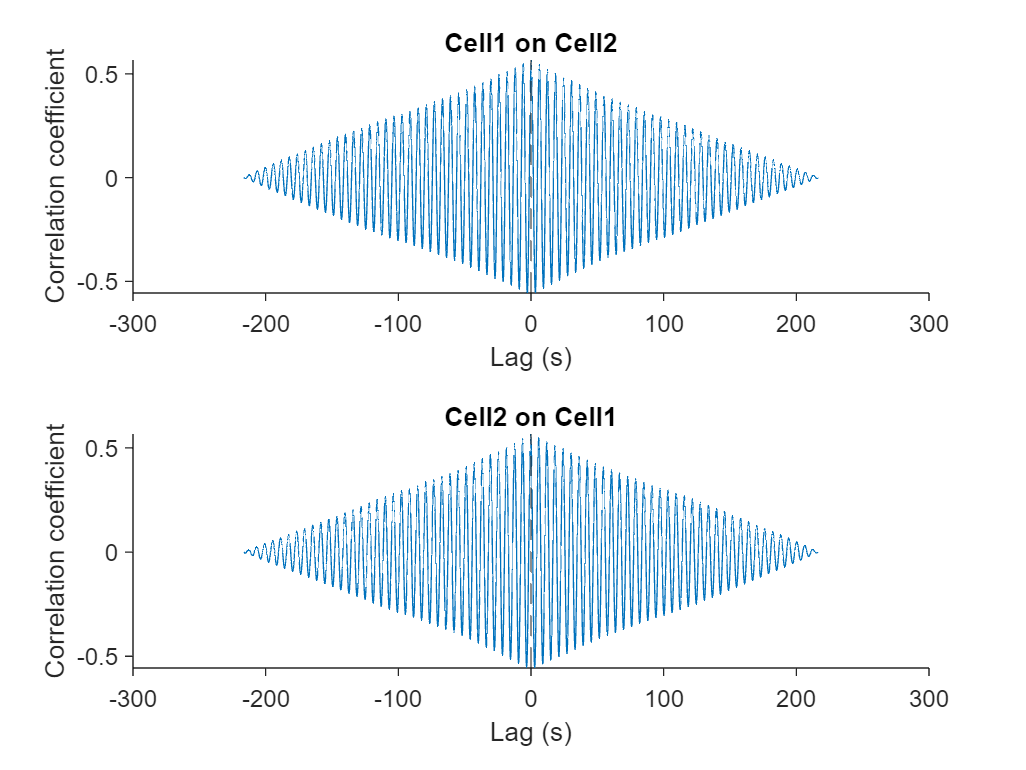

test(:,1) = test(:,1)-test(1,1);
mylag = sort([-test(2:end,1); test(:,1)]);
mycross_fd = xcov(test(:,2), test(:,3), 'normalized');
mycross_rv = xcov(test(:,3), test(:,2), 'normalized');
fig1 = tiledlayout("vertical");
nexttile
plot(mylag,mycross_fd);
set(gca, 'Box','off','TickDir','out')
xlabel('Lag (s)')
ylabel('Correlation coefficient')
title('Cell1 on Cell2')
xline(0, '--')
nexttile
plot(mylag,mycross_rv);
set(gca, 'Box','off','TickDir','out')
xlabel('Lag (s)')
ylabel('Correlation coefficient')
title('Cell2 on Cell1')
xline(0, '--')

[mymax_fd, indxmax_fd] = max(mycross_fd);
timemax_fd = mylag(indxmax_fd);

[mymin_fd, indxmin_fd] = min(mycross_fd);
timemin_fd = mylag(indxmin_fd);


[mymax_rv, indxmax_rv] = max(mycross_rv);
timemax_rv = mylag(indxmax_rv);

[mymin_rv, indxmin_rv] = min(mycross_rv);
timemin_rv = mylag(indxmin_rv);


valuezerolag_fd = mycross_fd (mylag==0);
valuezerolag_rv = mycross_rv (mylag==0);

crosstable = table(mylag, mycross_fd, mycross_rv);
crosstable.Properties.VariableNames = {'Lag (s)', 'Non-filtered Correlation Coefficient Forward', 'Non Filtered Correlation Coefficient Reverse' };

resulttable (1, :) = table(mymax_fd, timemax_fd, valuezerolag_fd, mymin_fd, timemin_fd);
resulttable(2,:) = table(mymax_rv, timemax_rv, valuezerolag_rv, mymin_rv, timemin_rv);
resulttable = addvars(resulttable, {'Non Filtered forward'; 'Non Filtered reverse'}, 'Before', 1);
resulttable.Properties.VariableNames = {'Result Type','Max CrossCorrelation', 'Lag MaxCorrelation (s)', ...
                                         'CrossCorrelation at 0s', ...
                                         'Min CrossCorrelation', 'Lag MinCorrelation (s)'};

**Lowpass filtering and repeat**

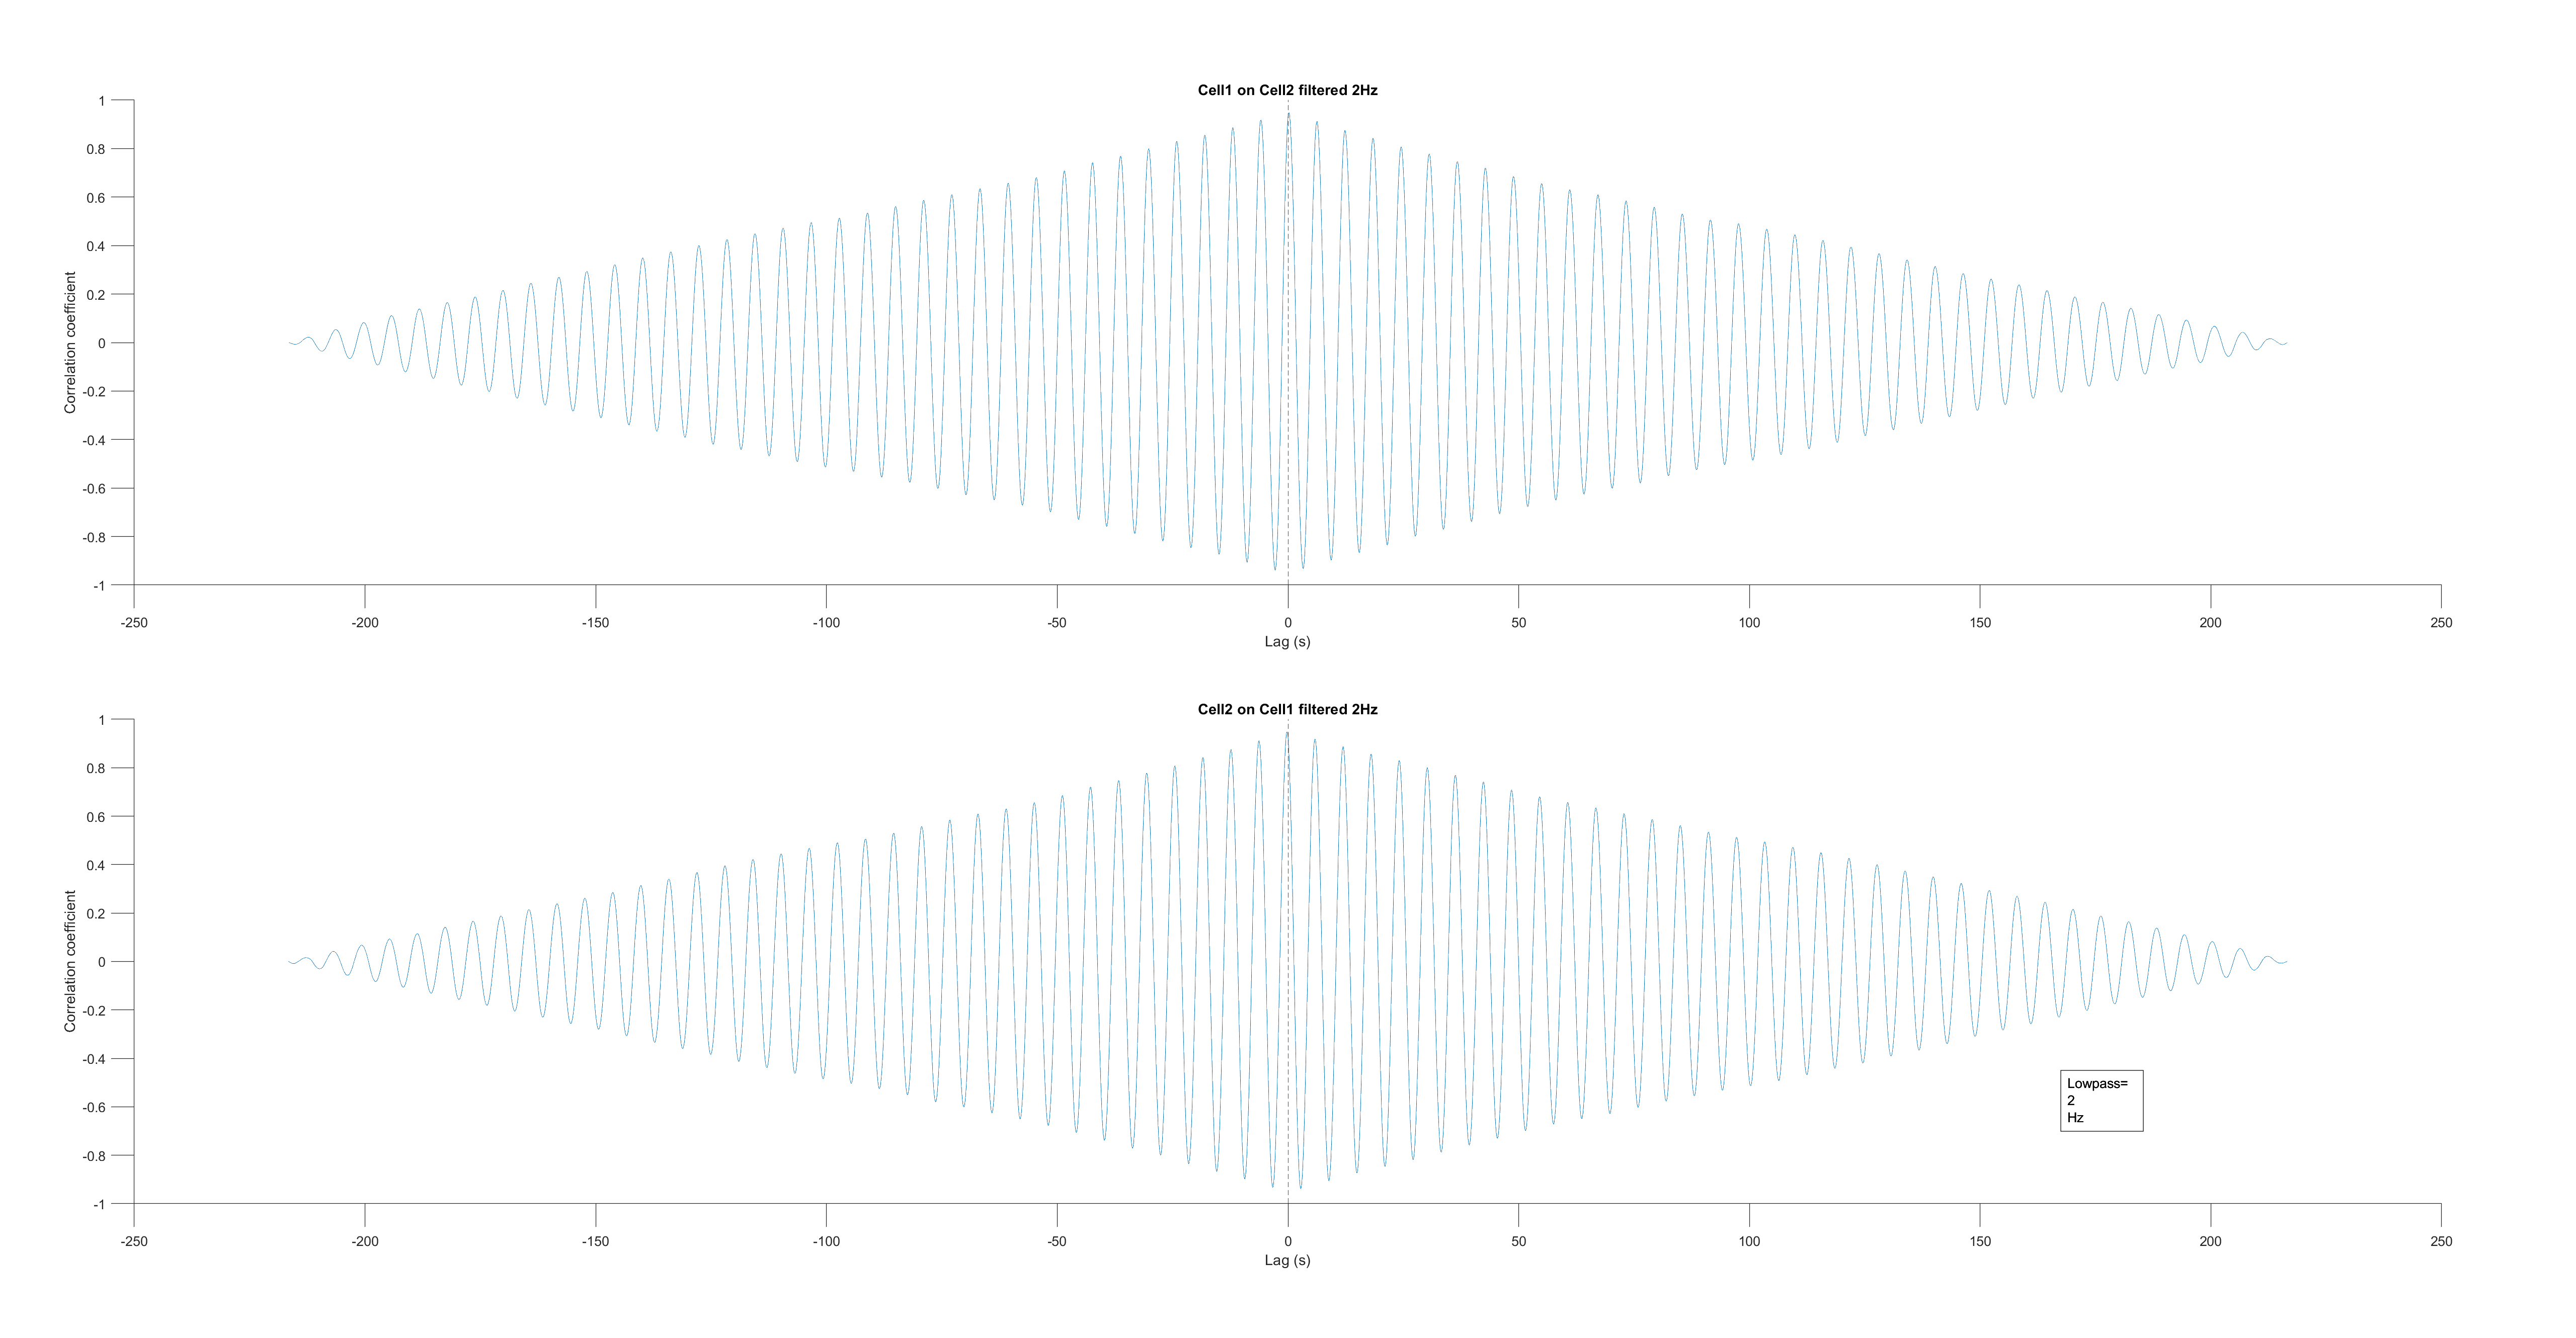

my_answer = questdlg('Do you want to lowpass filter your data?', 'Lowpass Filter', 'Yes', 'No', 'Yes');

switch my_answer
    case 'Yes'
        [filtered, lp_fq] = lowpassfilteringV2(test);
        mycross_fd_filt = xcov(filtered(:,2), filtered(:,3), 'normalized');
        mycross_rv_filt = xcov(filtered(:,3), filtered(:,2), 'normalized');
        fig2 = tiledlayout ("vertical");
        nexttile
        plot(mylag,mycross_fd_filt);
        set(gca, 'Box','off','TickDir','out')
        xlabel('Lag (s)')
        ylabel('Correlation coefficient')
        title(['Cell1 on Cell2 filtered ', num2str(lp_fq), 'Hz'])
        xline(0, '--')
        nexttile 
        plot(mylag,mycross_rv_filt);
        set(gca, 'Box','off','TickDir','out')
        xlabel('Lag (s)')
        ylabel('Correlation coefficient')
        title(['Cell2 on Cell1 filtered ', num2str(lp_fq), 'Hz'] )
        xline(0, '--')
        

        [mymax_fd_filt, indxmax_fd_filt] = max(mycross_fd_filt);
        timemax_fd_filt = mylag(indxmax_fd_filt);

        [mymin_fd_filt, indxmin_fd_filt] = min(mycross_fd_filt);
        timemin_fd_filt = mylag(indxmin_fd_filt);
        valuezerolag_fd_filt = mycross_fd_filt (mylag==0);

        [mymax_rv_filt, indxmax_rv_filt] = max(mycross_rv_filt);
        timemax_rv_filt = mylag(indxmax_rv_filt);

        [mymin_rv_filt, indxmin_rv_filt] = min(mycross_rv_filt);
        timemin_rv_filt = mylag(indxmin_rv_filt);
        valuezerolag_rv_filt = mycross_rv_filt (mylag==0);
        
        crosstable(:,4:5) = table(mycross_fd_filt, mycross_rv_filt); 
        crosstable = renamevars (crosstable, ["Var4","Var5"], ["Filtered Correlation Coefficient Forward", ...
                                                                "Filtered Correlation Coefficient Reverse"]);
        resulttable(3,:) = table ({['Filtered Forward ', num2str(lp_fq), 'Hz']}, mymax_fd_filt, timemax_fd_filt, valuezerolag_fd_filt, mymin_fd_filt, timemin_fd_filt);
        resulttable(4,:) = table ({['Filtered Reverse ', num2str(lp_fq), 'Hz']}, mymax_rv_filt, timemax_rv_filt, valuezerolag_rv_filt, mymin_rv_filt, timemin_rv_filt);
end

**Saving and exporting figures**

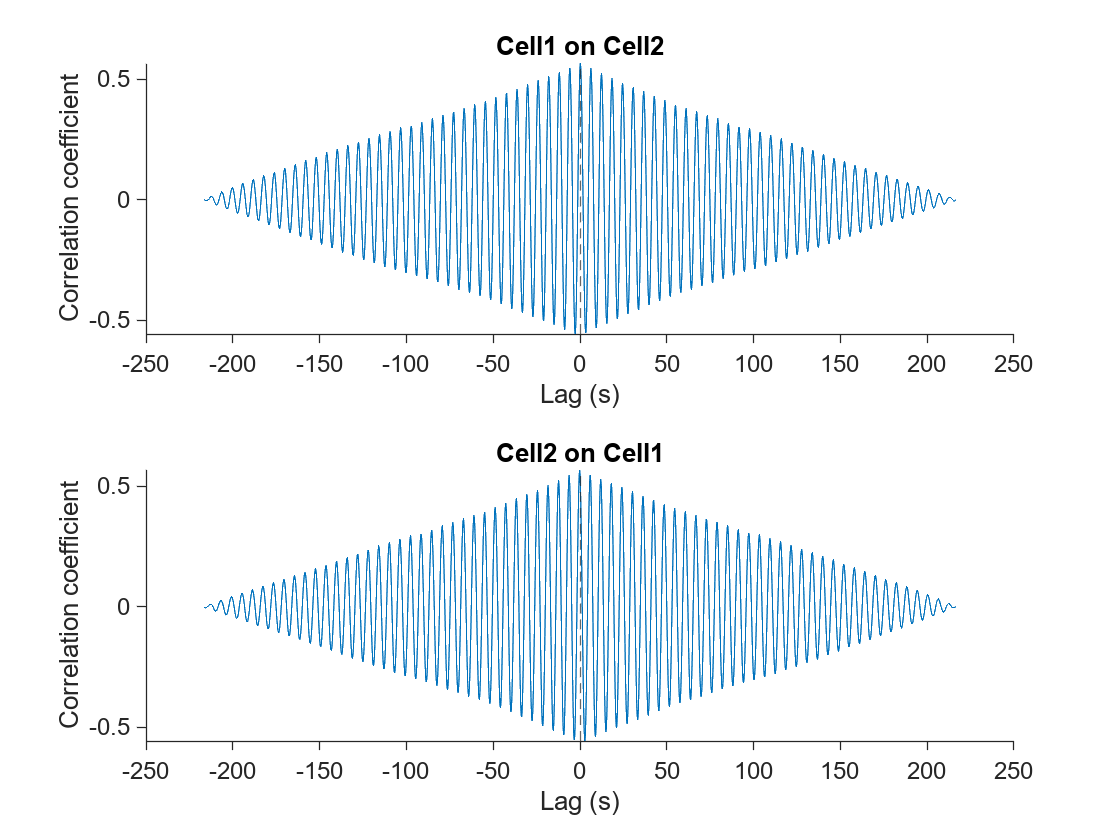

filename_noext = strrep(filename, '.abf', '');

q = questdlg('Do you want to save the results and export the figures?', 'Save Menu', 'Yes', 'No', 'Yes');

if matches(q, 'Yes')
    mkdir (pathname, [filename_noext '_results']);    
    exportgraphics(fig1, [pathname '\' filename_noext '_results' '\' 'xcorrelogram_nonfiltered.pdf'], 'ContentType', 'vector');
    if exist ('fig2', 'var')
       exportgraphics(fig2, [pathname '\' filename_noext '_results' '\' 'xcorrelogram_filtered.pdf' ], 'ContentType','vector');
    end

    writetable (resulttable,  [pathname '\' filename_noext '_results' '\' filename_noext '_results.csv'])
    writetable(crosstable, [pathname '\' filename_noext '_results' '\' 'xcorrelogram.csv'] )
    close all
    winopen([pathname '\' filename_noext '_results']);
else
    warndlg('The results have not been saved')
    close all
end